# Abundance-growth space of a microbial community: toy example

## Author(s): Sebastián N. Mendoza, Center for Mathematical Modeling, University of Chile, Chile. MATLAB implementation based on the Python code and tutorials of N.E. Jiménez et al. ([https://github.com/mathomics/ecosystem](https://github.com/mathomics/ecosystem))

## Reviewer(s):

## INTRODUCTION

Constraint-based models of microbial communities are usually analyzed by maximizing a community objective (e.g. the total biomass), which imposes a particular composition of the community. Jiménez et al. [1] proposed instead to explore the *abundance-growth space* of a community: a two-dimensional space defined by the fraction of each member in the community (abundance) and the community growth rate. Each point of this space is characterized qualitatively by flux variability analysis (FVA), and points are clustered according to their qualitative flux states, revealing abundance-dependent metabolic phenotypes without assuming any community objective.

For a community of two members with fraction $f$ (member 1) and $1-f$ (member 2) growing at a community rate $\mu$, the growth rate of each member is fixed to


$$\mu_1 = f \mu, \quad \mu_2 = (1-f)\mu$$


and the bounds of the reactions of each member are scaled by its fraction in the community (Chan et al. [2]). The qualitative state of a reaction is obtained from its minimum and maximum fluxes:

`code label meaning`

`-3 - fixed negative flux`

`-2 -- variable negative flux`

`-1 -0 negative or zero flux`

`0 0 zero flux`

`1 0+ zero or positive flux`

`2 ++ variable positive flux`

`3 + fixed positive flux`

`4 -+ negative or positive flux`

In this tutorial we reproduce the toy example of the supplementary material of [1] (notebook `sup_toy_example.ipynb`), a community of two organisms that compete for substrate A, while organism 2 produces B, which can be used by organism 1:

**Organism 1**: `A_e -> A_c`, `A_c -> E_c`, `A_c -> D_c`, `D_c -> 4 G_c`, `E_c -> 2 G_c`, `B_e -> B_c`, `B_c -> 10 G_c`, `G_c -> biomass`.

**Organism 2**: `A_e -> A_c`, `A_c -> B_c`, `B_c -> B_e`, `B_c -> 10 C_c`, `C_c -> biomass`.

## MATERIALS - EQUIPMENT SETUP

- MATLAB. No additional MATLAB toolbox is required.

- The COBRA Toolbox, initialized with `initCobraToolbox`. The functions used in this tutorial are in the folder `src/analysis/ecosystem`.

- A solver for linear programming problems (e.g. Gurobi, IBM CPLEX or GLPK).

global CBTDIR
if isempty(CBTDIR)
    initCobraToolbox(false);
end
% use Gurobi if available, GLPK otherwise
if ~changeCobraSolver('gurobi', 'LP', 0)
    changeCobraSolver('glpk', 'LP');
end
% solver tolerances of 1e-7 (default tolerance of cobrapy, used by the Python implementation)
changeCobraSolverParams('LP', 'optTol', 1e-7);
changeCobraSolverParams('LP', 'feasTol', 1e-7);

## PROCEDURE

## Step 1: Build the member models

**TIMING**: < 1 s

We build both models with `createModel` and `addReaction`. Exchange reactions are written as `met_e -> |. The biomass reaction of each organism (|biomass`) is set as its objective.

org1 = createModel();
org1 = addReaction(org1, 'Atr', 'reactionFormula', 'A_e -> A_c', 'printLevel', 0);
org1 = addReaction(org1, 'EX_A', 'reactionFormula', 'A_e -> ', 'lowerBound', -1000, 'printLevel', 0);
org1 = addReaction(org1, 'Btr', 'reactionFormula', 'B_e -> B_c', 'printLevel', 0);
org1 = addReaction(org1, 'EX_B', 'reactionFormula', 'B_e -> ', 'printLevel', 0);
org1 = addReaction(org1, 'AE', 'reactionFormula', 'A_c -> E_c', 'printLevel', 0);
org1 = addReaction(org1, 'AD', 'reactionFormula', 'A_c -> D_c', 'printLevel', 0);
org1 = addReaction(org1, 'DG', 'reactionFormula', 'D_c -> 4 G_c', 'printLevel', 0);
org1 = addReaction(org1, 'EG', 'reactionFormula', 'E_c -> 2 G_c', 'printLevel', 0);
org1 = addReaction(org1, 'BG', 'reactionFormula', 'B_c -> 10 G_c', 'printLevel', 0);
org1 = addReaction(org1, 'Gbio', 'reactionFormula', 'G_c -> biom1_c', 'printLevel', 0);
org1 = addReaction(org1, 'biomass', 'reactionFormula', 'biom1_c -> ', 'printLevel', 0);
org1 = changeObjective(org1, 'biomass');

org2 = createModel();
org2 = addReaction(org2, 'Atr', 'reactionFormula', 'A_e -> A_c', 'printLevel', 0);
org2 = addReaction(org2, 'EX_A', 'reactionFormula', 'A_e -> ', 'lowerBound', -1000, 'printLevel', 0);
org2 = addReaction(org2, 'EX_B', 'reactionFormula', 'B_e -> ', 'printLevel', 0);
org2 = addReaction(org2, 'AB', 'reactionFormula', 'A_c -> B_c', 'printLevel', 0);
org2 = addReaction(org2, 'Btr', 'reactionFormula', 'B_c -> B_e', 'printLevel', 0);
org2 = addReaction(org2, 'BC', 'reactionFormula', 'B_c -> 10 C_c', 'printLevel', 0);
org2 = addReaction(org2, 'Cbio', 'reactionFormula', 'C_c -> biom2_c', 'printLevel', 0);
org2 = addReaction(org2, 'biomass', 'reactionFormula', 'biom2_c -> ', 'printLevel', 0);
org2 = changeObjective(org2, 'biomass');

## Step 2: Build the community model

**TIMING**: < 1 s

`createEcosystemModel` renames the reactions and metabolites of each member with its prefix and connects every exchanged metabolite to a shared pool compartment. For an exchange `met_e ->` of member `k`, the community contains the member exchange `k_EX_met: k_met_e` [`=`](#=)` met_e_pool` and the pool exchange `EX_met_e: met_e_pool` [`=`](#=). Note that the biomass reactions (`biom1_c ->`) are also boundary reactions, so the biomass of each member is exchanged through the pool (`EX_biom1_c`, `EX_biom2_c`). The objective of the community model is the sum of the member objectives.

eco = createEcosystemModel({org1, org2}, {'org1', 'org2'}, ...
    'communityName', 'toy-example', 'communityID', 'org1-org2');

1. Storing exchanged metabolites information ...
2. Updating member model objects ids ...
3. Storing member objectives ...
4. Merging member models ...
{'org1_biomass': 1}
{'org2_biomass': 1}
5. Creating pool compartment, metabolites and reactions ...
6. Updating compartment names ...
Done. Community model created
Created community model from 2 member models:
General stats:
model (0):
	 id = , prefix = org1
		 reactions = 11
		 exchange metabolites = 3
model (1):
	 id = , prefix = org2
		 reactions = 8
		 exchange metabolites = 3
community model:
	 id = org1-org2, name = toy-example
		 reactions = 23
		 exchange metabolites = 4
Exchange metabolite conflicts (formula, charge, name, id) = 0
Community exchange reaction bounds: (-1000, 1000)


printRxnFormula(eco.model, eco.model.rxns);

org1_Atr	org1_A_e 	->	org1_A_c 
org1_EX_A	org1_A_e 	<=>	A_e_pool 
org1_Btr	org1_B_e 	->	org1_B_c 
org1_EX_B	org1_B_e 	->	B_e_pool 
org1_AE	org1_A_c 	->	org1_E_c 
org1_AD	org1_A_c 	->	org1_D_c 
org1_DG	org1_D_c 	->	4 org1_G_c 
org1_EG	org1_E_c 	->	2 org1_G_c 
org1_BG	org1_B_c 	->	10 org1_G_c 
org1_Gbio	org1_G_c 	->	org1_biom1_c 
org1_biomass	org1_biom1_c 	->	biom1_c_pool 
org2_Atr	org2_A_e 	->	org2_A_c 
org2_EX_A	org2_A_e 	<=>	A_e_pool 
org2_EX_B	org2_B_e 	->	B_e_pool 
org2_AB	org2_A_c 	->	org2_B_c 
org2_Btr	org2_B_c 	->	org2_B_e 
org2_BC	org2_B_c 	->	10 org2_C_c 
org2_Cbio	org2_C_c 	->	org2_biom2_c 
org2_biomass	org2_biom2_c 	->	biom2_c_pool 
EX_A_e	A_e_pool 	<=>	
EX_B_e	B_e_pool 	<=>	
EX_biom1_c	biom1_c_pool 	<=>	
EX_biom2_c	biom2_c_pool 	<=>	


disp(eco.model.rxns(eco.model.c ~= 0))

    {'org1_biomass'}
    {'org2_biomass'}



## Step 3: Set the simulation conditions

**TIMING**: < 1 s

`setEcosystemPoolBounds` changes the bounds of the pool exchange reactions. The parameter `bioCons` (biological constraint) limits the uptake of each member: the lower bound of the member exchange reactions is set to `bioCons` when the metabolite can enter the pool. The community can take up to 10 units of A from the environment, and B is not available in the environment (it can only be produced by organism 2).

eco = setEcosystemPoolBounds(eco, {'A_e'}, [-10 1000], -20);
eco = setEcosystemPoolBounds(eco, {'B_e'}, [0 1000], -20);

## Step 4: Select the reactions to analyze

**TIMING**: < 1 s

The qualitative FVA and the clustering are computed on the non-blocked reactions of the community model (`eco.rxn2cluster`).

eco = setEcosystemClusterReactions(eco);

Missing FCA results
Using non-blocked reactions only
Total reactions considered for fva and clustering: 23


## Step 5: Build the abundance-growth grid

**TIMING**: < 1 s

The maximum community growth is computed by maximizing the sum of the member objectives in a relaxed problem (positive lower bounds such as ATP maintenance are removed), without considering the abundance of each member. A grid of `numPoints` x `numPoints` points is built over the fraction of organism 1 ($f \in [0, 1]$) and the community growth ($\mu \in [0, \mu_{max}]$). The point (0, 0) is removed.

**TIP**: use a small number of points when exploring a new model, and increase it gradually, since computation times increase with the number of points.

eco = buildEcosystemGrid(eco, 'numPoints', 10);

Maximum community: 100


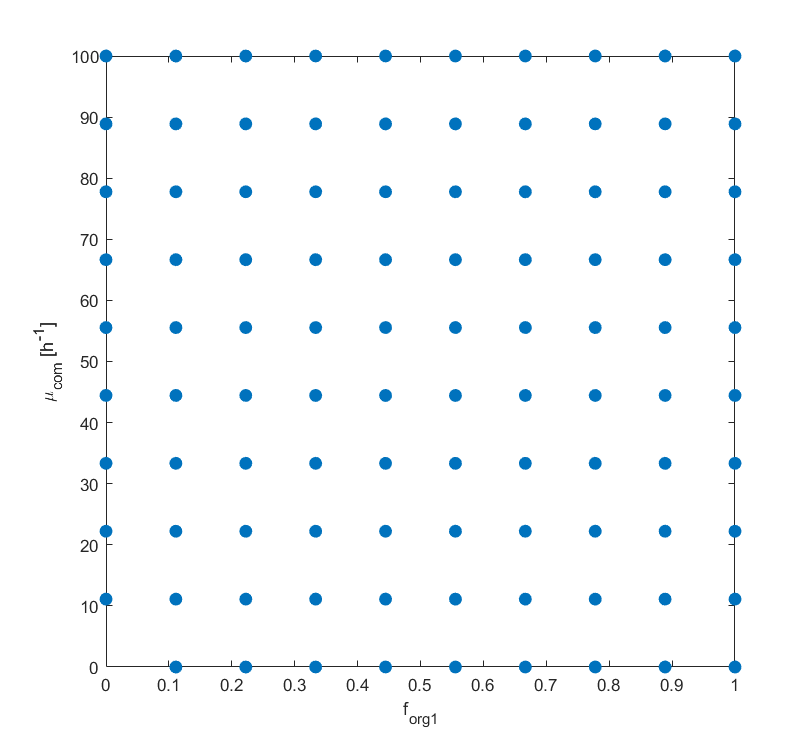

plotEcosystemGrid(eco, 'toPlot', 'none', 'markerSize', 60, 'xlabel', 'f_{org1}');

## Step 6: Feasibility of the grid points

**TIMING**: ~1 s

Each point is feasible if the community model admits a steady state when the member growth rates are fixed to $f\mu$ and $(1-f)\mu$ and the bounds of the member reactions are scaled by the member fractions (`updateBounds`).

eco = checkEcosystemGridFeasibility(eco, 'updateBounds', true);

grid feasible points: 82 / 99


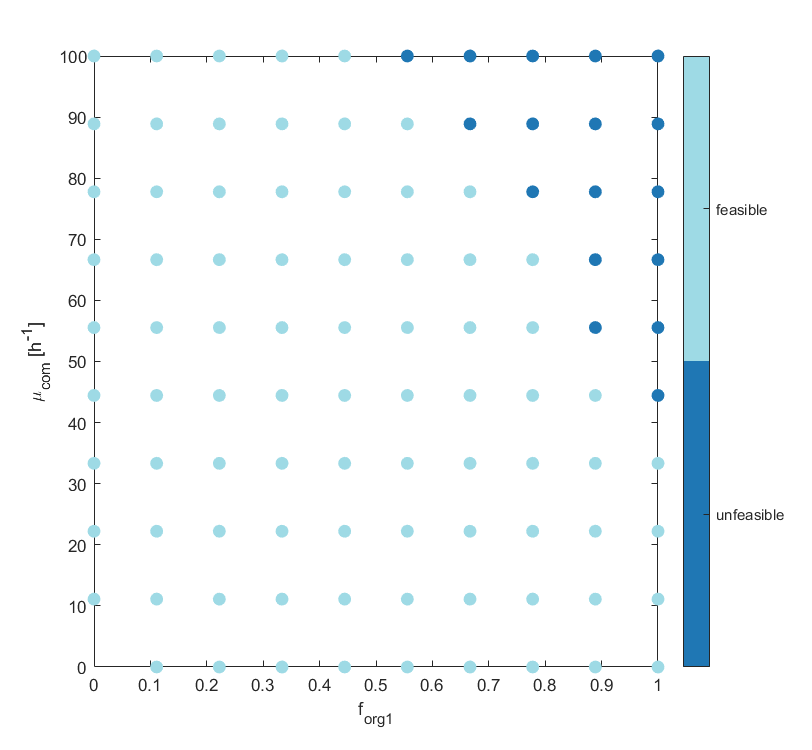

plotEcosystemGrid(eco, 'toPlot', 'feasible', 'colormap', 'tab20', 'xlabel', 'f_{org1}');

## Step 7: Qualitative flux variability analysis

**TIMING**: ~10 s

FVA is computed on each feasible point and translated into qualitative states. As in the original notebook, we restrict the analysis to exchange reactions.

eco.rxn2cluster = eco.rxn2cluster(contains(eco.rxn2cluster, 'EX_'));
eco = ecosystemQualitativeFVA(eco, 'updateBounds', true);

Running qualitative fva over grid feasible points...
Qualitative FVA computed for 82 points and 8 reactions.


array2table(eco.qualVectors(1:5, :), 'VariableNames', eco.rxn2cluster)

ans = 5x8 table
    EX_A_e    EX_B_e    EX_biom1_c    EX_biom2_c    org1_EX_A    org1_EX_B    org2_EX_A    org2_EX_B
    ______    ______    __________    __________    _________    _________    _________    _________

      -1        1           0             0             0            0           -1            1    
      -1        1           0             0             0            0           -1            1    
      -1        1           0             0             0            0           -1            1    
      -1        1           0             0             0            0           -1            1    
      -1        1           0             0             0            0           -1            1    


## Step 8: Clustering of the grid points

**TIMING**: < 1 s

The Jaccard distance between the qualitative vectors of the feasible points is computed and the points are grouped by hierarchical clustering (Ward linkage) into `k` clusters. The distances, the linkage and the cluster labels are computed as in SciPy, used by the Python implementation.

eco = clusterEcosystemPoints(eco, 'method', 'hierarchical', 'k', 8);

Calculating jaccard distances between grid points...
Clustering grid points ...
Done!


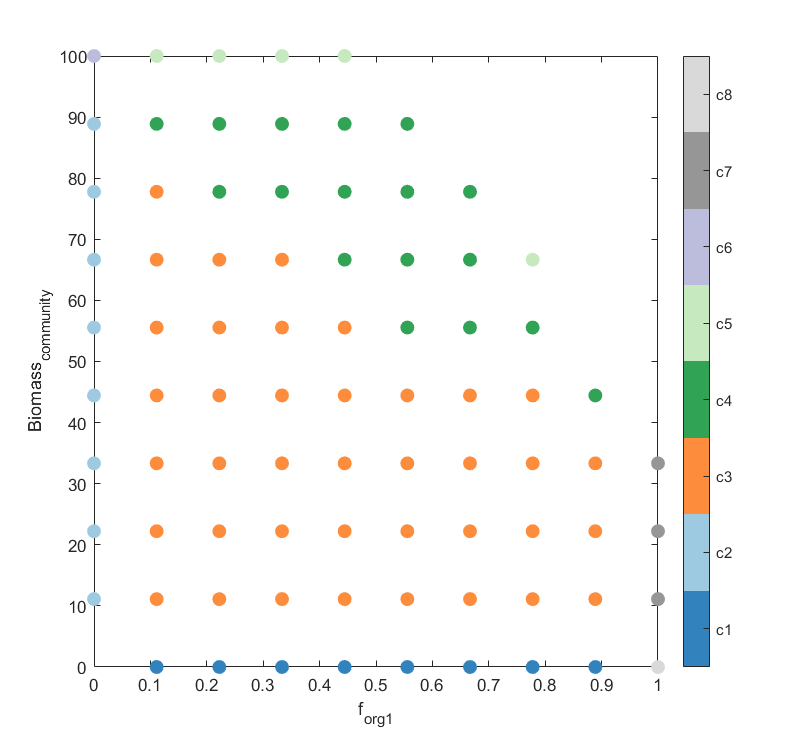

plotEcosystemGrid(eco, 'toPlot', 'cluster', 'colormap', 'tab20c', 'markerSize', 70, ...
    'xlabel', 'f_{org1}', 'ylabel', 'Biomass_{community}');

Qualitative changes in this system are associated with increased biomass production and changes in community composition. For instance, the structural plasticity (`-0`) of organism 1 is gradually replaced by flux plasticity (`--`) while increasing biomass requirements.

## Step 9: Representative qualitative states of each cluster

**TIMING**: < 1 s

`getEcosystemClusterReactionValues` returns, for each reaction and cluster, the qualitative state exhibited by at least a fraction `thr` of the points of the cluster (`NaN` if no state reaches the threshold). With `changing = true` only reactions whose representative states differ in at least two clusters are reported.

[repTable, repValues, rxnIds] = getEcosystemClusterReactionValues(eco, 'thr', 0.8, 'changing', true)

repTable = 8x8 table
                    c1        c2        c3        c4       c5       c6        c7       c8  
                  ______    ______    ______    ______    _____    _____    ______    _____

    EX_A_e        {'-0'}    {'--'}    {'--'}    {'--'}    {'-'}    {'-'}    {'--'}    {'0'}
    EX_B_e        {'0+'}    {'0+'}    {'0+'}    {'0+'}    {'0'}    {'0'}    {'0' }    {'0'}
    EX_biom1_c    {'0' }    {'0' }    {'+' }    {'+' }    {'+'}    {'0'}    {'+' }    {'0'}
    EX_biom2_c    {'0' }    {'+' }    {'+' }    {'+' }    {'+'}    {'+'}    {'0' }    {'0'}
    org1_EX_A     {'0' }    {'0' }    {'-0'}    {'-0'}    {'0'}    {'

repValues =     -1    -2    -2    -2    -3    -3    -2     0
     1     1     1     1     0     0     0     0
     0     0     3     3     3     0     3     0
     0     3     3     3     3     3     0     0
     0     0    -1    -1     0     0    -2     0
     0     0    -1    -2    -3     0     0     0
    -1    -2    -2    -2    -3    -3     0     0
     1     1     1     2     3     0     0     0


rxnIds = 8x1 cell array
    {'EX_A_e'    }
    {'EX_B_e'    }
    {'EX_biom1_c'}
    {'EX_biom2_c'}
    {'org1_EX_A' }
    {'org1_EX_B' }
    {'org2_EX_A' }
    {'org2_EX_B' }


`compareEcosystemClusters` reports the reactions whose representative states change between two clusters, e.g. clusters 3 and 4:

compTable = compareEcosystemClusters(repValues, rxnIds, 'c3', 'c4')

compTable = 2x2 table
                   c3        c4  
                 ______    ______

    org1_EX_B    {'-0'}    {'--'}
    org2_EX_B    {'0+'}    {'++'}


## Step 10: Quantitative flux coupling analysis

**TIMING**: ~30 s

The functional relationship between two reactions can be studied on selected points of the grid. For each requested point, the closest feasible grid point is selected, the flux of the first reaction is fixed to values spanning its feasible range and the minimum and maximum fluxes of the second reaction are computed. Fluxes of member reactions are normalized by the member fraction. Here we study the uptake of A by both organisms.

gridX = [0.2, 0.4, 0.6, 0.8];
gridY = [60, 40, 20];
qfca = quantitativeFluxCoupling(eco, gridX, gridY, {'org1_EX_A', 'org2_EX_A'}, 'nSteps', 50);

Quantitative Flux Coupling analysis
 Initializing grid...
the closest point to [0.2, 60] is [0.2222, 55.5556], at a distance of 4.444
the closest point to [0.4, 60] is [0.4444, 55.5556], at a distance of 4.445
the closest point to [0.6, 60] is [0.5556, 55.5556], at a distance of 4.445
the closest point to [0.8, 60] is [0.7778, 55.5556], at a distance of 4.444
the closest point to [0.2, 40] is [0.2222, 44.4444], at a distance of 4.444
the closest point to [0.4, 40] is [0.4444, 44.4444], at a distance of 4.445
the closest point to [0.6, 40] is [0.5556, 44.4444], at a distance of 4.445
the closest point to [0.8, 40] is [0.7778, 44.4444], at a distance of 4.444
the closest point to [0.2, 20] is [0.2222, 22.2222], at a distance of 2.222
the closest point to [0.4, 20] is [0.4444, 22.2222], at a distance of 2.223
the closest point to [0.6, 20] is [0.5556, 22.2222], at a distance of 2.223
the closest point to [0.8, 20] is [0.7778, 22.2222], at a distance of 2.222
Selected point [0.2222 55.5556

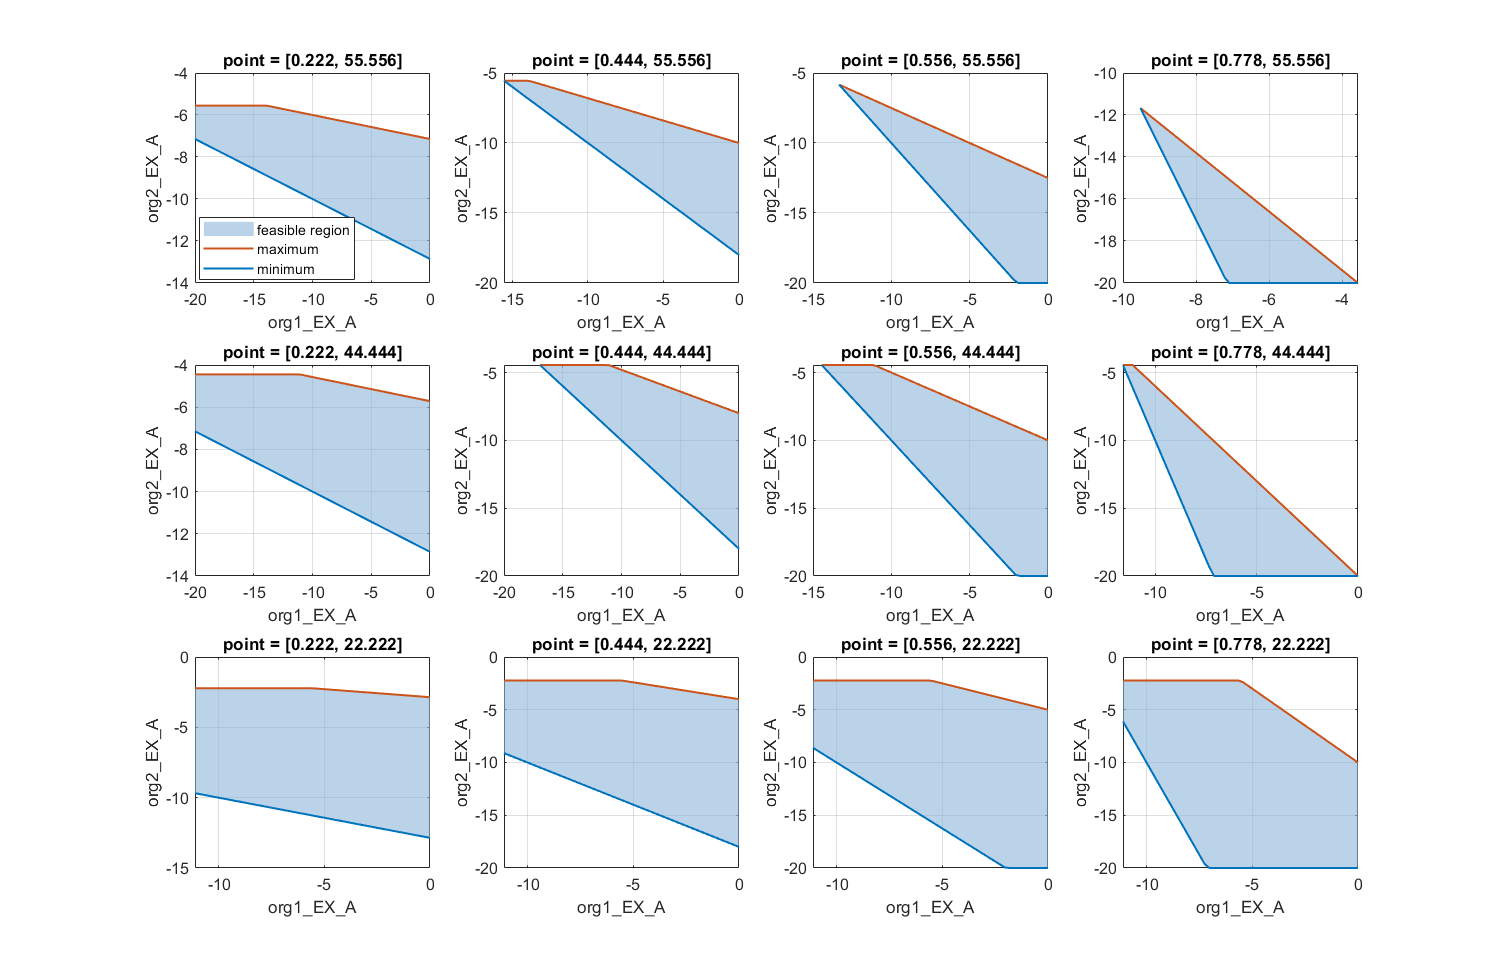

plotQuantitativeFluxCoupling(qfca, 'colWrap', 4);

## TROUBLESHOOTING

- **Problem**: `fluxVariability` or `optimizeCbModel` return errors or infeasible results for every point. **Possible reason**: no LP solver has been set. **Solution**: run `changeCobraSolver` with an available solver (e.g. `changeCobraSolver('glpk', 'LP')`).

- **Problem**: the qualitative vectors contain many states `0+` or `-0` that should be zero. **Possible reason**: numerical noise of the solver larger than the threshold `delta` (default 1e-9). **Solution**: use a larger threshold, e.g. `ecosystemQualitativeFVA(eco, 'delta', 1e-6)`.

- **Problem**: cluster labels differ from those of the original notebook. **Possible reason**: small numerical differences between LP solvers can change the qualitative states of some points (the clustering itself gives the same labels as SciPy). **Solution**: compare clusters through their representative states instead of their labels.

## TIMING

- Steps 1-6: ~2 s

- Step 7: ~10 s

- Steps 8-9: < 1 s

- Step 10: ~30 s

## ANTICIPATED RESULTS

The maximum community growth is 100 and 82 of the 99 grid points are feasible. With 8 clusters, the representative states of the exchange reactions are the same as in the original notebook:

| c1 c2 c3 c4 c5 c6 c7 c8|

`EX_A_e -0 -- -- -- - - -- 0`

`EX_B_e 0+ 0+ 0+ 0+ 0 0 0 0`

`EX_biom1_c 0 0 + + + 0 + 0`

`EX_biom2_c 0 + + + + + 0 0`

`org1_EX_A 0 0 -0 -0 0 0 -- 0`

`org1_EX_B 0 0 -0 -- - 0 0 0`

`org2_EX_A -0 -- -- -- - - 0 0`

`org2_EX_B 0+ 0+ 0+ ++ + 0 0 0`

and clusters 3 and 4 differ in the exchange of B: in cluster 3 organism 1 may or may not take B (`-0`) and organism 2 may or may not secrete it (`0+`), whereas in cluster 4 B is necessarily cross-fed from organism 2 (`++`) to organism 1 (`--`).

## REFERENCES

[1] Jiménez, N.E., Acuña, V., Cortés, M.P., Eveillard, D., Maass, A. Unveiling abundance-dependent metabolic phenotypes of microbial communities. *mSystems* **8**, e00492-23 (2023).

[2] Chan, S.H.J., Simons, M.N., Maranas, C.D. SteadyCom: predicting microbial abundances while ensuring community stability. *PLoS Comput. Biol.* **13**, e1005539 (2017).